$F_c$ - driving force - $[N]$

$\eta_g$ - gearbox efficiency - $[-]$

$K_g$ - gear ratio - $[-]$

$r_{mp}$ - motor pinion radius (prumer pastorku) - $[m]$


$$F_c = \frac{\eta_g K_g \tau_M}{r_{mp}
}$$


$M_c$- mass of the cart - $[kg]$

$x_C$ - cart position - $[m]$

$B_{eq}$ - equivalent viscous damping coefficient - $[\frac{N m\; s}{rad}]$ 

eta_g = 0.9 %gearbox efficiency

eta_g = 0.9000

K_g = 3.71 %gearbox gear ratio

K_g = 3.7100

k_t = 7.68*0 %motor current-torque constant

k_t = 0

k_m = 7.68*0 %motor back-emf constant

k_m = 0

R_m = 2.6 %motor armature resistance

R_m = 2.6000

r_mp = 6.35e-3 %motor pinion radius (prumer pastorku)

r_mp = 0.0064

eta_m = 0.69 %motor efficiency

eta_m = 0.6900

A_m = eta_g * K_g * eta_m * k_t / r_mp / R_m %actuator gain

A_m = 0

J_p = 1.2e-3 %moment of inertia about CoM, medium length pendulum

J_p = 0.0012

L_p = 0.3365 %full length of the pendulum

L_p = 0.3365

l_p = L_p/2

l_p = 0.1683

M_p = 0.127 %pendulum mass

M_p = 0.1270

%J_p = J_pCoM + M_p * l_p^2
M_c = 0.38 %cart mass

M_c = 0.3800

J_m = 3.9e-7 %motor moment of inertia

J_m = 3.9000e-07

J_eq = M_c + eta_g*K_g^2*J_m/r_mp^2

J_eq = 0.4998

B_eq = 4.3 %equivalent viscous damping coefficient (cart)

B_eq = 4.3000

B_p = 0.0024 %equivalent viscous damping coefficient (pendulum)

B_p = 0.0024

g = 9.81

g = 9.8100


%syms eta_g K_g k_t k_m R_m r_mp eta_m A_m J_p L_p l_p M_p m_c j_m J_eq B_eq B_p g
syms x_c(t) alpha(t) V_m u

%sila pusobici na cart
F_c = (eta_g*K_g*k_t/R_m/r_mp)*(-K_g*k_m*diff(x_c,t)/r_mp + eta_m*V_m) %2.11 LinPendulumGantry

$$F\_c(t) = 0$$


%rovnice systemu (2.9 a 2.10 v LinearPendulumGantry)
disp("2.9 a 2.10")

2.9 a 2.10


ode1 = (J_eq+M_p)*diff(x_c,t,2) + M_p*l_p*cos(alpha)*diff(alpha,t,2) - M_p*l_p*sin(alpha)*diff(alpha,t)^2 == F_c - B_eq*diff(x_c,t);
ode2 = M_p*l_p*cos(alpha)*diff(x_c,t,2) + (J_p+M_p*l_p^2)*diff(alpha,t,2) + M_p*l_p*g*sin(alpha) == -B_p*diff(alpha,t);

ode1 = subs(ode1, V_m, u);
ode2 = subs(ode2, V_m, u);

odes = [ode1, ode2];
odes = simplify(odes)

$$odes(t) = \begin{array}{l} \left(\begin{array}{cc} 30794173100078695\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{2}+6196953087261802496\,\frac{\partial }{\partial t}x_{c}\left(t\right)+903334142283111360\,\sigma_{1}=30794173100078695\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2} & \frac{1888067738198575\,\sin\left(\alpha \left(t\right)\right)}{9007199254740992}+\frac{6158834620015739\,\cos\left(\alpha \left(t\right)\right)\,\sigma_{1}}{288230376151711744}+\frac{5528401504798809\,\sigma_{2}}{1152921504606846976}=-\frac{3\,\frac{\partial }{\partial t}\alpha \left(t\right)}{1250} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right) \end{array}$$

[V, S] = odeToVectorField(odes);
nonlinearSystem = matlabFunction(V, 'vars', {'t', 'Y', 'u'});

fh_tmp = matlabFunction(V, 'vars', {'Y', 'u'});
x = sym('x', [1 4]);
V = fh_tmp(x, u);
V = simplify(V);
V = vpa(V, 2)

$$V = \left(\begin{array}{c} x_{2}\\ \frac{1.3e+15\,\cos\left(x_{1}\right)\,\sin\left(x_{1}\right)\,{x_{2}}^{2}+4.2e+15\,x_{2}+3.7e+17\,\sin\left(x_{1}\right)-2.6e+17\,x_{4}\,\cos\left(x_{1}\right)}{1.3e+15\,{\cos\left(x_{1}\right)}^{2}-8.5e+15}\\ x_{4}\\ -\frac{1.0\,\left(3.0e+17\,\sin\left(x_{1}\right)\,{x_{2}}^{2}+1.5e+17\,\cos\left(x_{1}\right)\,x_{2}-5.9e+19\,x_{4}+1.3e+19\,\cos\left(x_{1}\right)\,\sin\left(x_{1}\right)\right)}{1.3e+18\,{\cos\left(x_{1}\right)}^{2}-8.7e+18} \end{array}\right)$$

A_sym = jacobian(V, x);
B_sym = jacobian(V, u);

x_operating = [0, 0, 0, 0];
A = subs(A_sym, [x, 0], [x_operating, 0]);
B = subs(B_sym, [x, 0], [x_operating, 0]);

A = double(A)

A =          0    1.0000         0         0
  -51.5448   -0.5902         0   36.0450
         0         0         0    1.0000
    1.7571    0.0201         0   -8.0888


B = double(B)

B =      0
     0
     0
     0


C = [1 0 0 0]

C =      1     0     0     0


D = 0

D = 0


linearSystem = ss(A,B,C,D);

disp("Poles:")

Poles:


eigs(A)

ans =   -7.5314 + 0.0000i
  -0.5738 + 6.8280i
  -0.5738 - 6.8280i
   0.0000 + 0.0000i



disp("Poles of a subsystem without x_C:")

Poles of a subsystem without x_C:


A_sub = A;
A_sub(3,:) = [];
A_sub(:,3) = [];
eigs(A_sub)

ans =   -7.5314 + 0.0000i
  -0.5738 + 6.8280i
  -0.5738 - 6.8280i


initialCondition = [pi/16, 0, 0, 0] %alpha, Dalpha, xc, Dxc

initialCondition =     0.1963         0         0         0


simulationTime = 20;

solutionNonlinear = ode15s(nonlinearSystem, [0 simulationTime], initialCondition);
[y, t, x] = initial(linearSystem, initialCondition, simulationTime);
solutionLinear = struct;
solutionLinear.t = t;
solutionLinear.x = x;


f1 = figure

f1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


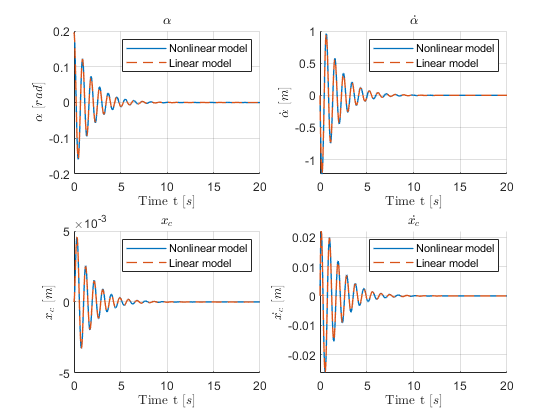

subplot(221);
hold on
grid on
plot(solutionNonlinear.x, solutionNonlinear.y(1,:), "LineWidth", 1)
plot(solutionLinear.t, solutionLinear.x(:,1), "LineWidth", 1, "LineStyle","--")
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\alpha$ [$rad$]', 'Interpreter', 'Latex')
  title('$\alpha$', 'Interpreter', 'Latex')
  
  subplot(222);
hold on
grid on
plot(solutionNonlinear.x, solutionNonlinear.y(2,:), "LineWidth", 1)
plot(solutionLinear.t, solutionLinear.x(:,2), "LineWidth", 1, "LineStyle","--")
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{\alpha}$ [$m$]', 'Interpreter', 'Latex')
  title('$\dot{\alpha}$', 'Interpreter', 'Latex')
  
  subplot(223);
hold on
grid on
plot(solutionNonlinear.x, solutionNonlinear.y(3,:), "LineWidth", 1)
plot(solutionLinear.t, solutionLinear.x(:,3), "LineWidth", 1, "LineStyle","--")
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$x_c$ [$m$]', 'Interpreter', 'Latex')
  title('$x_c$', 'Interpreter', 'Latex')
  
  subplot(224);
hold on
grid on
plot(solutionNonlinear.x, solutionNonlinear.y(4,:), "LineWidth", 1)
plot(solutionLinear.t, solutionLinear.x(:,4), "LineWidth", 1, "LineStyle","--")
legend("Nonlinear model", "Linear model")
 xlabel('Time t [$s$]','interpreter','latex')
 ylabel('$\dot{x_c}$ [$m$]', 'Interpreter', 'Latex')
  title('$\dot{x_c}$', 'Interpreter', 'Latex')